# Data description

HIV Associated Neurocognitive Disorder (HAND) is a recent development in the aging HIV population. Due to both toxicities in the therapies used to treat the disease or from HIV itself, patients are beginning to have deficits in their psychomotor functions as well as short-term memory loss. This is further exacerbated by the use of illicit drugs; a common co-variate with HIV infection. The Total Modified Hopkins Dementia Score (TMHDS) is a tool that is used to assess this in large patient populations. The score ranges from 0 to 12 with a score of 10 or above being considered "normal".

The hopkinsdata.xlsx file contains the data from a study of a cocaine abusing HIV-1 cohort. Patients were asked to return approximately 6 months apart for 6 visits and during their study visit they were subjected to the TMHD test and blood was drawn for subsequent drug testing.

The Excel file has three worksheets, containing the age, drug, and score data. Each row represents a patient and each column represents a visit.

% function hw2_primer()

## Variable names

- The *age* variable contains the age at the time of visit for each patient (rows are patients and columns are visits).

- The *drug* variable contains the information on whether the patient tested positive for cocaine (True) or did not (False) at each visit.

- The *score* variable contains the TMHDS for each patient at each visit.

## Objectives:

- Understand the data.  Two main independent variables (age & drug use) and one possibly dependent one (TMHDS).  TMHDS may depend on either one or both. 

- Read the individual tab of an excel file into a cell array with xlsread() 

- ttest(), polyfit(), statistics of the line fit fitlm()

- box plot,  scatter plot

- captions and conclusions

## Load the data

Read the age, drug, and score worksheets in the Excel file into age, drug, score variables.

age=xlsread('hopkinsdata.xlsx', 'age'); % read numeric data into age matrix. 
drug=xlsread('hopkinsdata.xlsx', 'drug');
score=xlsread('hopkinsdata.xlsx', 'score');

# Variation in drug use and age

The data has two main independent variables (age & drug use) and one possibly dependent one (TMHDS). First, we want to see how much general variation exists in each one. Histograms are perfect for this.

refresh: mean (, 2)  compute the mean of each row;  hist (); subplot....

avguse = mean(drug, 2); 

Unrecognized function or variable 'drug'.

%subplot(m,n,p); divides the current figure into an m-by-n grid and creates axes in the position specified by p
%hist(avguse)
% If you are not happy with the automatically determined binsizes, you can 
% specify your own bins to the hist() function:


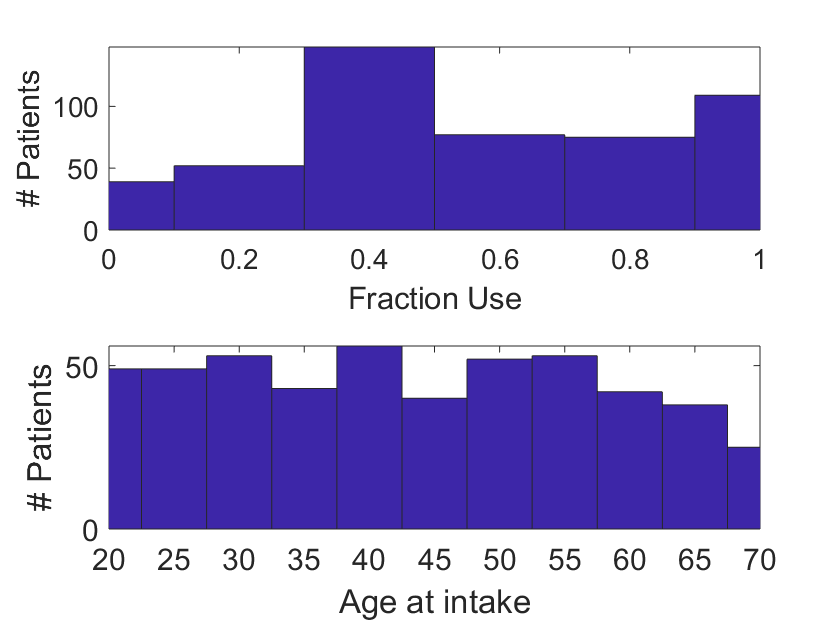


subplot(2,1,1)
hist(avguse, 0:0.2:1.1) % hist() is old, try the better function histogram(). This is how you improve
xlim([0, 1])
xlabel('Fraction Use', 'fontsize', 15, 'fontweight', 'bold')
ylabel('# Patients', 'fontsize', 15, 'fontweight', 'bold')
set(subplot(2,1,1), 'FontSize', 14)

subplot(2,1,2)
hist(age(:,1), 15:5:70) % age distribution of first visit
xlim([20, 70])
xlabel('Age at intake', 'fontsize', 15, 'fontweight', 'bold')
ylabel('# Patients', 'fontsize', 15, 'fontweight', 'bold')
set(subplot(2,1,2), 'FontSize', 15)

**Figure Caption:** The cohort represents a middle-aged population of moderate drug-users. **Top:** A histogram showing the number of patients grouped by the fraction of times the patient tested positive for cocaine. **Bottom:** A histogram showing the number of patients grouped by their age at intake.

%...fprintf

## Now a caption

All captions should have the following: - Title Sentence: This should deliver the main point of the figure - Explanation of the source of the data behind each plot. - Explanation of all axes.

**Figure Caption:** The cohort represents a middle-aged population of moderate drug-users. **Top:** A histogram showing the number of patients grouped by the fraction of times the patient tested positive for cocaine. **Bottom:** A histogram showing the number of patients grouped by their age at intake.

# How much does drug use affect Hopkins score (Drug vs. Score)?

First we'll look at the short term effects: effect of drug use at a visit, on the score during that visit.

%Let's look at first visit:
% boxplot https://www.mathworks.com/help/stats/boxplot.html. 
% red line (median); the top and bottom edges(75th and 25th pecentile); + (outliners)
% max and minimum
% whiskers
useatvisit = drug(:, 1); % first visit


figure;


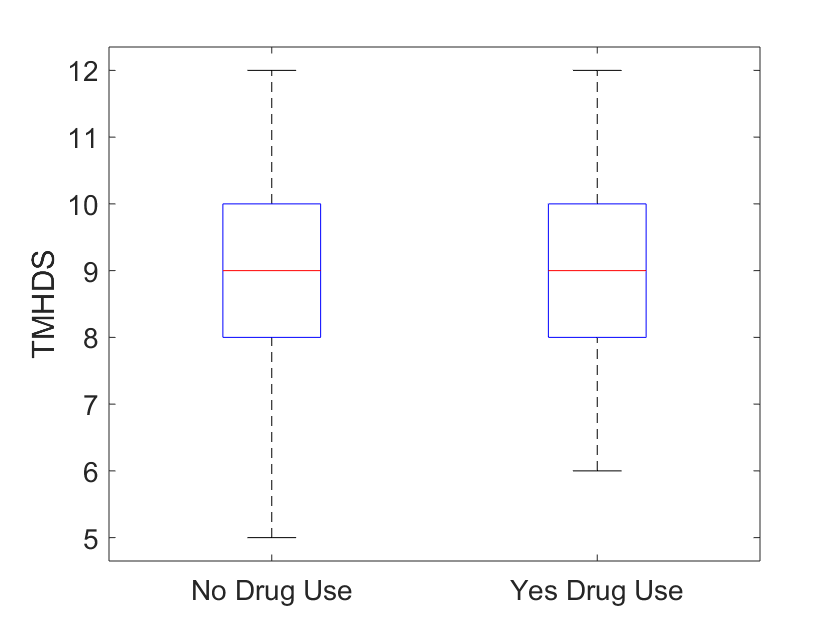

boxplot(score(:, 1), useatvisit, 'labels', {'No Drug Use', 'Yes Drug Use'})
ylabel('TMHDS', 'fontsize', 15, 'fontweight', 'bold')
set(gca, 'FontSize', 14) % set current axwsor chart gca

Is it still true at other visits?

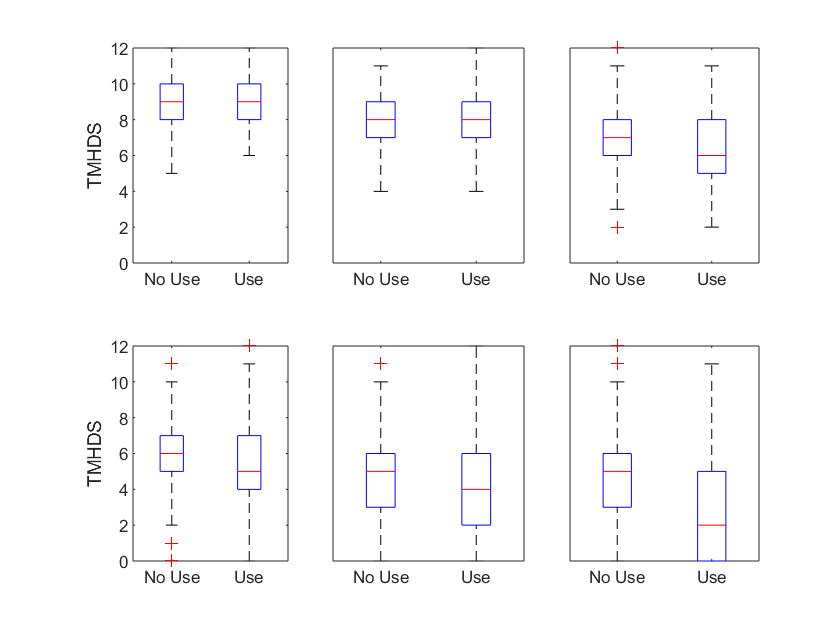

for col = 1:6
	useatvisit = drug(:, col);
	h = subplot(2, 3, col);
	boxplot(score(:, col), useatvisit, 'labels', {'No Use', 'Use'})
	ylim([0 12])
	if col==1 || col==4 % only put y labels on col 1 and 4 plots
		ylabel('TMHDS', 'fontsize', 15, 'fontweight', 'bold')
	else
		h.YTick=[];
	end
end

## Use at all visits. `[h,p] = ttest2(``___``)`

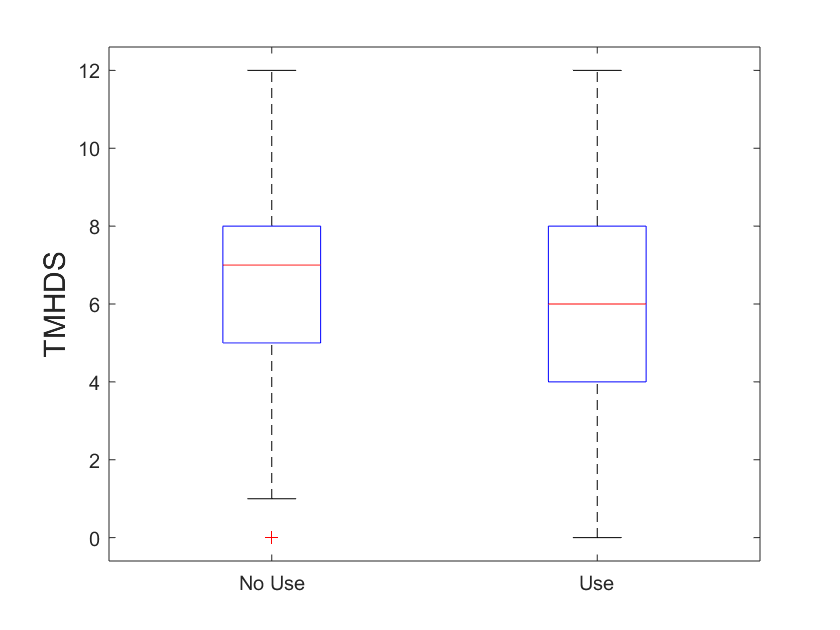


figure
boxplot(score(:), drug(:), 'labels', {'No Use', 'Use'}) % flatten the matrix. 
ylabel('TMHDS', 'fontsize', 15, 'fontweight', 'bold')

**Figure Caption:** Drug use at the time of visit does not significantly alter the TMHDS of a patient. For visits 1, 3, and 6 boxplots of the TMHDS are shown grouped by a positive drug test at the time of visit. The red-line indicates the mean TMHDS, the box shows the 25% & 75% percentiles.

## ttest2 to answer how much does drug use affect Hopkins score?


I=drug(:)==1; % convert (flatten) drug (500,6) to drug(500*6,1).  Generate a logical array I(3000,1) with the value of 1 if the drug use is 1
[~,pval]=ttest2(score(~I), score(I))

pval = 2.4562e-11

% Two-sample t-test: [h,p] = ttest2(x,y). https://www.mathworks.com/help/stats/ttest2.html
% [h,p] = ttest2(x,y) returns a test decision for the null hypothesis that the data in vectors x and y 
% comes from independent random samples from normal distributions with equal means and equal 
% but unknown variances, using the two-sample t-test ("x and y are the same"). 

% [h,p] = ttest2(x,y, alpha, 0.01) returns h and p values.  h can be 0 or 1. p is the p value 

% In this case, p will be compared to 0.01, if p>0.01 then h=1 and ttest will not reject the null hypothesis.  
% There is no difference between x and y. 
% Otherwise (p<0.01), h=0 rejection X and y are different at 0.01 % (99% confidence)
% the default alpha is 0.05 (5%) significance level.



[h,pval]=ttest2(score(~I), score(I))  % no 'Alpha', p value compare to .05 default

h = 1

pval = 2.4562e-11

[h,pval]=ttest2(score(~I), score(I), 'Alpha',0.01)

h = 1

pval = 2.4562e-11


if pval<0.05
	fprintf(['The difference between Use and NoUse groups for\n' ...
		' their TMHDS score across all visits is found significant\n' ...
		' at pvalue=%.2g\n'],pval);
else
	fprintf(['The difference between Use and NoUse groups for\n' ...
		' their TMHDS score across all visits is NOT found significant.']);
end

The difference between Use and NoUse groups for
 their TMHDS score across all visits is found significant
 at pvalue=2.5e-11


# What about the long-term effects of drug use (Age drug use and score)?

The previous analysis only looked at the effect of drug-use on a single visit, however, there is likely a cumulative effect of cocaine use on Hopkins score

Linear regression with polyfit(), [https://www.mathworks.com/help/matlab/ref/polyfit.html?searchHighlight=polyfit&s_tid=doc_srchtitle](https://www.mathworks.com/help/matlab/ref/polyfit.html?searchHighlight=polyfit&s_tid=doc_srchtitle) y=ax+b

trend=polyfit(): trend (0) =b, trend (1)=b

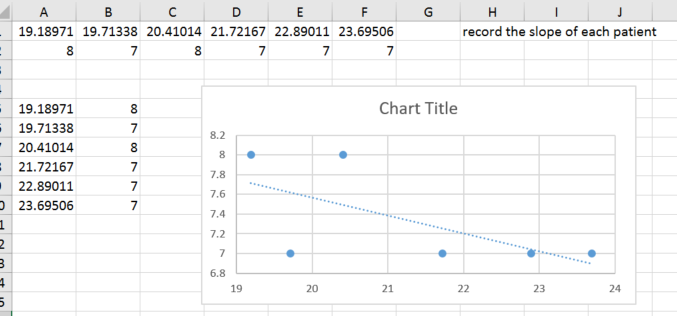

% First, figure out how much each patient is changing.
% each patient will have a dscore, which is the rate against age
dscore = zeros(size(score,1), 1); % 500 patients

for i = 1:size(score,1) % from 1 to 500
	trend = polyfit(age(i, :), score(i, :), 1);
	dscore(i) = trend(1);
end
 


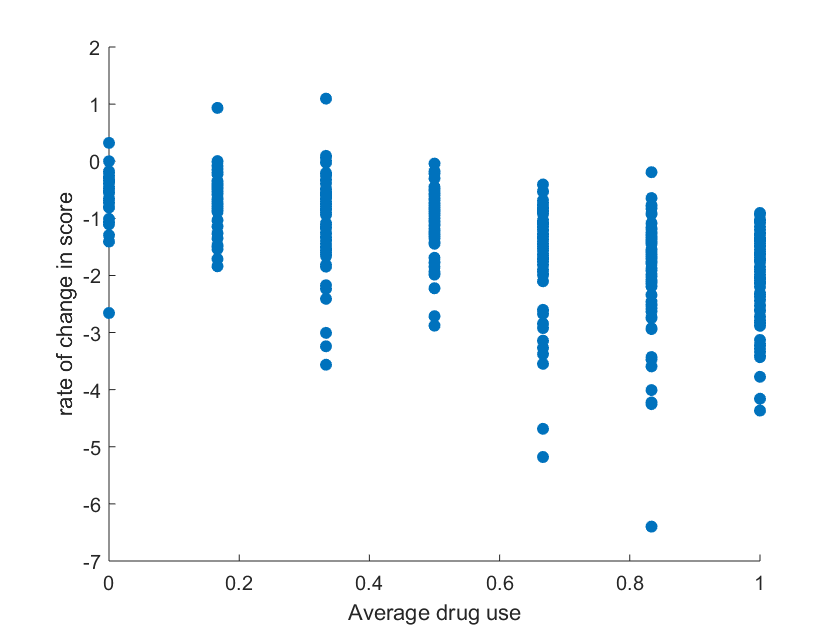

figure
h=scatter(avguse, dscore, 'filled'); % scatter (x, y)
xlabel('Average drug use'); ylabel('rate of change in score');

Lets make a box plot of the same data

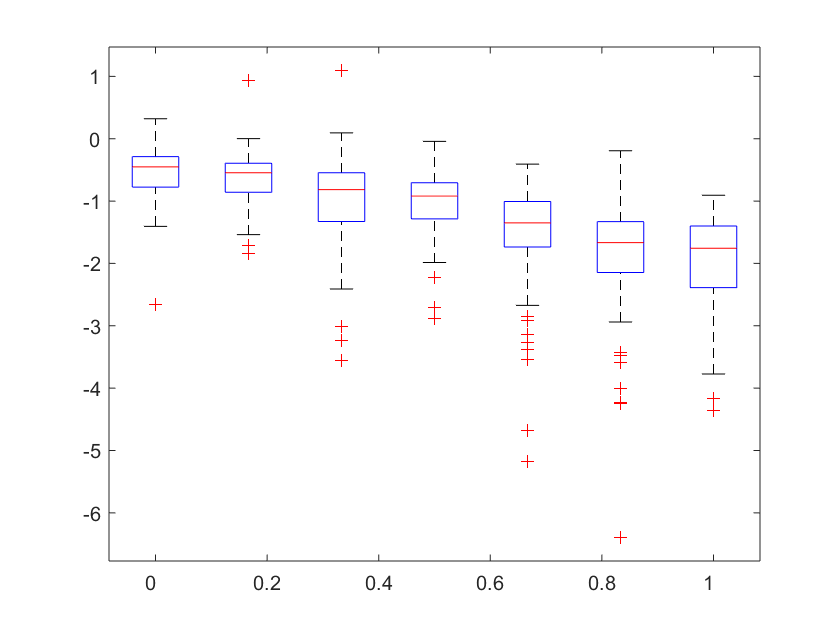

figure
boxplot(dscore, avguse, 'positions', (0:6)./6) % "positions" is a numeric vector
set(gca, 'XTick', 0:0.2:1, 'XTickLabel', 0:0.2:1) % set current axes or chart

clf
boxplot(dscore, avguse, 'positions', (0:6)./6)
set(gca, 'XTick', 0:0.2:1, 'XTickLabel', 0:0.2:1) % set current axes or chart

% Put a trend-line in
x=xlim;
trend = polyfit(avguse, dscore, 1);
hold on
plot(x, trend(1)*(x) + trend(2), 'm--', 'LineWidth', 2) % the first and last point.
plot(x, [0 0], 'k--')
grid on
hold off
trend(1)

ans = -1.5874

trend(2)

ans = -0.4336

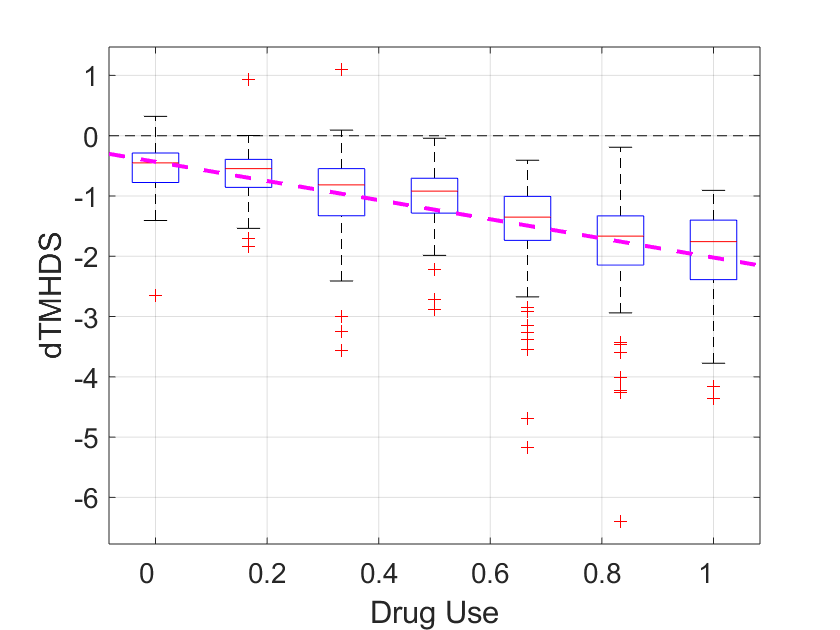

ylabel('dTMHDS', 'fontsize', 15, 'fontweight', 'bold')
xlabel('Drug Use', 'fontsize', 15, 'fontweight', 'bold')
set(gca, 'FontSize', 14)

**Figure Caption:** Increased drug use is correlated with a more rapid decline in Hopkins score. The rate of change of Hopkins score was estimated using a linear regression for each patient (dTMHDS/year). These scores were grouped by the fraction of times the patient tested positive for Cocaine. The red-line indicates the mean TMHDS, the box shows 25% & 75% percentiles, and the whiskers span 1 standard deviation of the data. The trendline is shown in magenta.

% Fit linear regression model filml()
% Statistics of the line fit(https://www.mathworks.com/help/stats/fitlm.html)
% p value indicates if the linear model is significant
mdl = fitlm(avguse, dscore)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)    -0.43363    0.069019    -6.2828    7.2609e-10
    x1              -1.5874     0.10356    -15.329    1.0054e-43


Number of observations: 500, Error degrees of freedom: 498
Root Mean Squared Error: 0.748
R-squared: 0.321,  Adjusted R-Squared 0.319
F-statistic vs. constant model: 235, p-value = 1.01e-43

c=mdl.Coefficients

c = 2×4 table
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)    -0.43363    0.069019    -6.2828    7.2609e-10
    x1              -1.5874     0.10356    -15.329    1.0054e-43


table2array(c('x1','pValue'))

ans = 1.0054e-43